# Beams: Example showing how to create and visualise beams

This example demonstrates how to create and use different kinds of optical tweezers toolbox (OTT) beams.  For more information, see the corresponding example in the OTT documentation and the `beam` package reference section.

% Add toolbox to path (uncomment this line if OTT is not already on the path)
%addpath('../../');

## Creating a beam

OTT provides two main methods for creating beams: using the classes in the `ott.beam` package and using the classes in the `ott.bsc` package. The `ott.beam` package is intended to provide a easy to use, high-level interface for interacting with beams. Internally, the `ott.beam` classes use the functions declared in `ott.bsc`, and in some cases, using the `ott.bsc` classes directly can give better run-times. However, for most users, the `ott.beam` classes should be adequate.

In this example, we will focus on the `ott.beam` package.

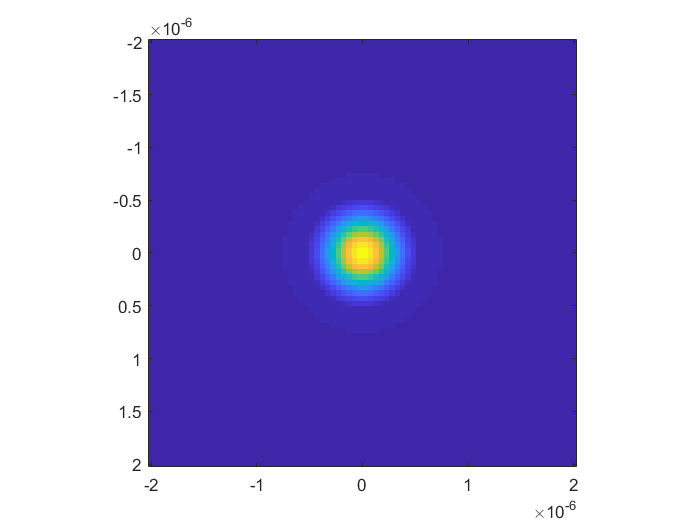

% The `beam` package provides several methods classes representing common
% beams.  For example, to create a beam, use
beam = ott.beam.Gaussian();

% This create the default Gaussian beam (see the documentation for the
% exact specification).  We can change the beam properties such as the
% medium speed and power using the beam's properties or methods, for example
beam.power = 0.1;           % Set power [Watts]
beam.speed = 3e8/1.33;      % Set speed [meters/second]

% Some properties, such as wavelength, need to be set using beam methods.
% Beams are not handle classes, as such, it is important to store the
% resulting beam object.  The following sets the wavelength by keeping the
% speed fixed:
beam = beam.setWavelength(532e-9, 'fixedSpeed'); % Set wavelength [meters]

% Alternatively, we can create the beam with the desired properties at
% the start by passing a list of named arguments to the constructor:
beam = ott.beam.Gaussian('power', 0.1, ...
    'index_medium', 1.33, 'omega', 2*pi*3e8/532e-9);

% To view our beam, we can use one of the beam visualisation methods,
% for example, the following creates a XY slice through the beam focus:
figure();
beam.visNearfield();

## Translating and rotating beams

Beams have a `position` and `rotation` property. These properties are applied to the beam whenever the beam is used (for example, when a visualisation method is called).

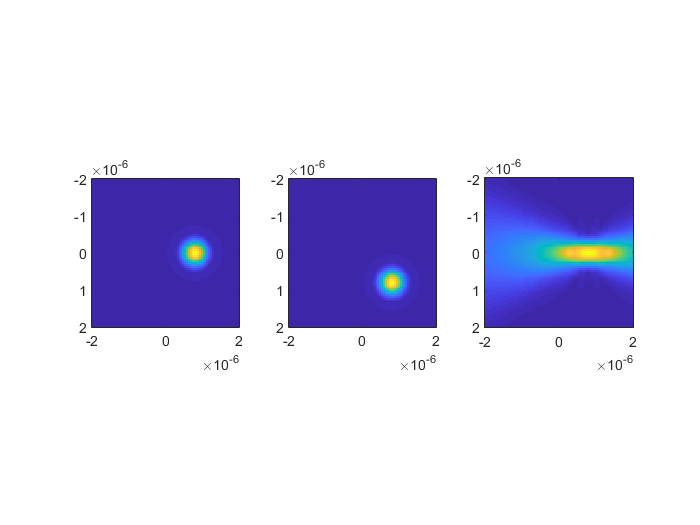

% The position property is a 3x1 numeric vector.  To shift the beam by
% 1 wavelength in the x direction, we can directly set the position property:
figure();
subplot(1, 3, 1);
beam.position = [2;0;0]*beam.wavelength;
beam.visNearfield();

% Alternatively, we can use the `translateXyz` method.  The translation
% method applies the translation on top of any existing displacement and
% returns a new copy of the beam, for example, to translate our previous beam
% along the Y-direction, we could use:
subplot(1, 3, 2);
tbeam = beam.translateXyz([0;2;0]*beam.wavelength);
tbeam.visNearfield();

% Rotations are stored as 3x3 rotation matrices.  As with the ``position``
% property, we can also directly set the ``rotation`` property, however
% it is often easier to use the ``rotate*`` methods.
%
% The following rotates the beam pi/2 radians about the Y axis.
% When the beam is used, the rotation is applied before the translation.
subplot(1, 3, 3);
rbeam = beam.rotateY(pi/2);
rbeam.visNearfield();

## Creating arrays of beams

The toolbox supports three kinds of arrays: Coherent arrays, Incoherent arrays, and generic arrays. Incoherent/Coherent arrays represent beams which can be represented by a finite set of sub-beams. Generic arrays are simply collections of multiple beams.

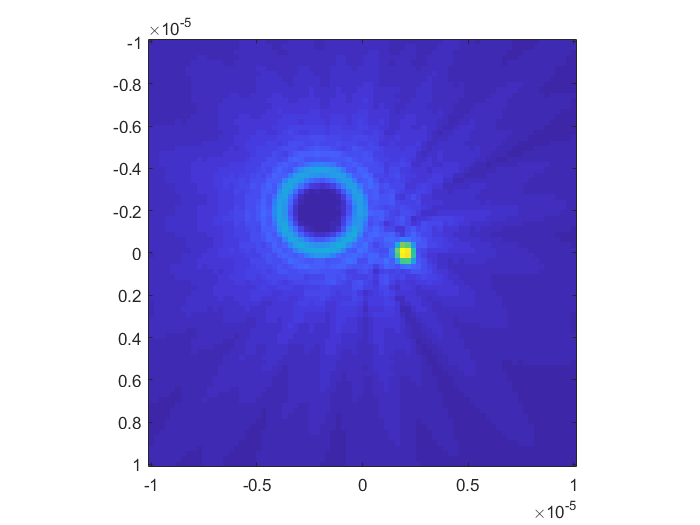

% To create a generic array, simply use Matlab's array syntax, for example
beam_array = [ott.beam.Gaussian(), ...
    ott.beam.LaguerreGaussian('lmode', 10)];

% Most operations can be applied to generic arrays.  The result is the
% same as applying the operation to each element of the array.  For example,
% to translate the array of beams
tbeams = beam_array.translateXyz([2;0;0]*beam.wavelength);

% Or to set the properties of each beam
[tbeams.position] = deal([5;0;0]*beam.wavelength);
tbeams(2).position = [-5;-5;0]*beam.wavelength;
tbeams(2).power = 2;

% Coherent and Incoherent arrays can be created using the Array
% class, for example
cbeams = ott.beam.Array(tbeams, 'arrayType', 'coherent');
figure();
cbeams.visNearfield('range', [1,1]*1e-5);

## Calculating the change in momentum between two beams

The `ott.beam.Beam` class provides methods for calculating the change in momentum between two beams. Although it is more common to calculate the force acting on a particle (see the ottForce.m example), the follow shows how to calculate the change in momentum between two beams.

beam1 = ott.beam.Gaussian('power', 0.1);
beam2 = beam1.rotateY(pi/2);
force = beam1.force(beam2)

force = 	1.0e+-9 *

    0.2224
   -0.0000
   -0.2224


## Creating a custom beam

Although the toolbox has several different beams commonly used in optical trapping (for a complete list, see the `beam` package reference section), it is sometimes necessary to create a custom beam. The most common scenario is when modelling an SLM or the experimentally measured field at the back aperture of the focussing objective. For this task we can use the `PmParaxial` class (for more control over the fields we could also use the `ott.bsc` classes). The following example shows how we could model a phase-only SLM illuminated by a Gaussian-like beam:

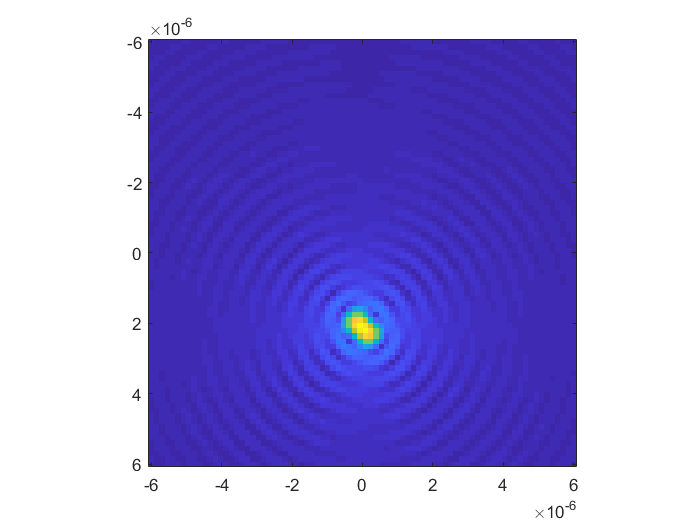

% Generate coordinates for pattern
x = linspace(-1, 1, 20);
y = linspace(-1, 1, 20);
[X, Y] = ndgrid(x, y);

% Calculate incident field
E0 = exp(-(X.^2 + Y.^2)./4);

% Calculate SLM-like pattern
kx = 2;
phi = 2*pi*kx*x;

% Calculate field at back aperture
E = E0 .* exp(1i*phi);

% Calculate beam
beam = ott.beam.PmParaxial.InterpProfile(X, Y, E, 'Nmax', 20);
figure();
beam.visNearfield('range', [1,1]*6e-6);

## Improving runtime

Toolbox beams are represented using a vector spherical wave function expansion.  Depending on how many terms are included in the expansion, visualisation and translation functions can take quite a while. One method to improve the runtime is to reduce the number of terms in the expansion.  By defaut, finite beams (such as Gaussians) are calcualted with ~10,000 terms and then truncated such that the resulting beam power doesnt drop bellow 2% of the original beam power.  This threshold can be changed using, for example, to change it to 10% use

ott.beam.BscFinite.getSetShrinkNmaxRelTol(0.01);

Next time we create a beam, it will use this new tolerance

beam = ott.beam.Gaussian();
disp(beam.data.Nmax);

    13



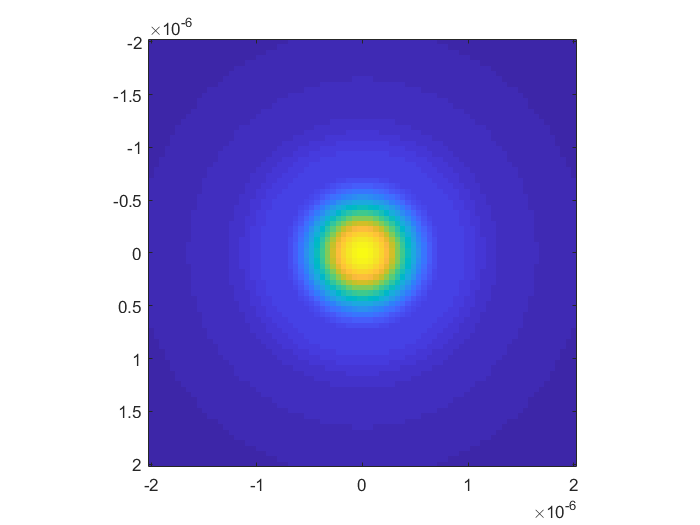

tic
beam.visNearfield();

toc

Elapsed time is 0.233302 seconds.



% Change back to 2%
ott.beam.BscFinite.getSetShrinkNmaxRelTol(0.02);

For repeated field calculation at the same locations, there is a lot of data that can be re-used in the field calculation functions.  Both the visNearfield and Gaussian beam generation functions require calculating fields.  To speed up these methods, we can store the field data from a previous run.  The following creates a plot with 2 different beams.

figure();
range = [1,1]*2e-6;

% Generage first beam with no prior data.  We use the recalculate
% method explicitly so we can get the returned data for repeated
% calculations.  For visualisation, we also get the returned data,
% but we also need to specify the plot axes explicitly to show the plot.
subplot(1, 2, 1);
tic
beam = ott.beam.LaguerreGaussian('lmode', 9, 'calculate', false);
[beam, dataBm] = beam.recalculate([]);
[~, ~, dataVs] = beam.visNearfield('range', range, 'plot_axes', gca());
toc

Elapsed time is 2.156502 seconds.


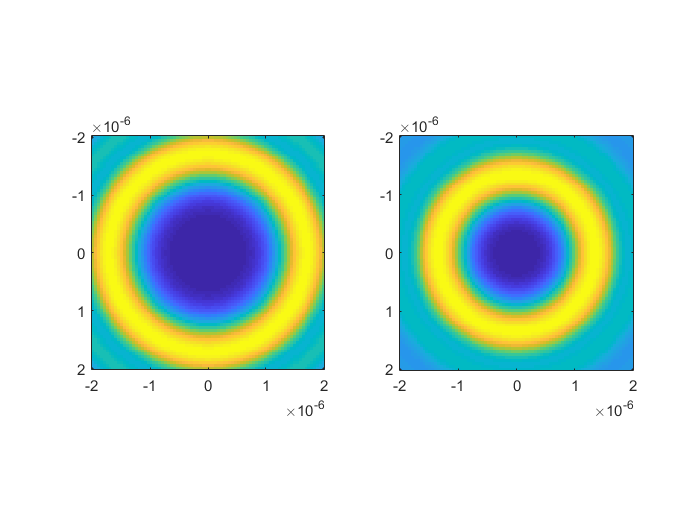


% Generate second beam with prior data for both beam and visNearfield.
subplot(1, 2, 2);
tic
beam = ott.beam.LaguerreGaussian('lmode', 7, 'calculate', false);
beam = beam.recalculate([], 'data', dataBm);
beam.visNearfield('range', range, 'data', dataVs);

toc

Elapsed time is 1.891270 seconds.


Different beams/methods support different optional parameters. It is not always faster to pass the data structure as an input. See the documentation for notes on improving speed and the supported arguments these methods support.

## About

This example live script is part of OTT.  Written by Isaac Lenton.  For further details see [https://github.com/ilent2/ott](https://github.com/ilent2/ott)